Opgaver

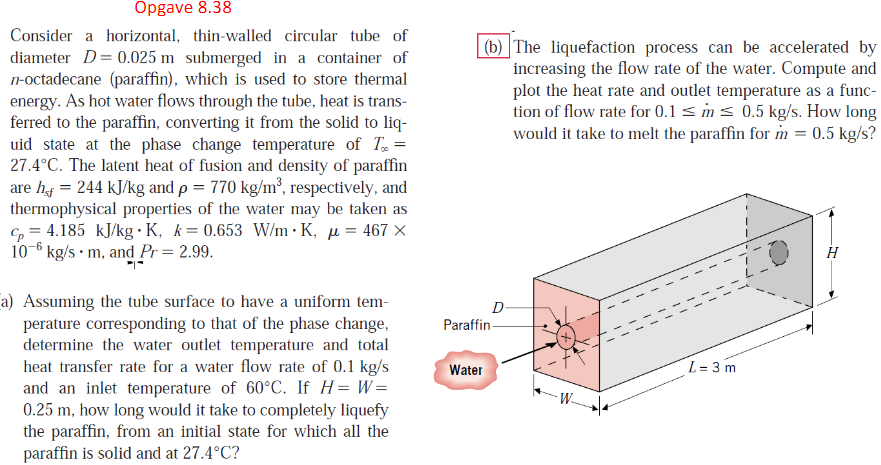

clear all
clf
D = 0.025;
T_inf = 27.4 + 273.15; % K % phase change of paraffin
c_p = 4185; % J/kg
h_sf = 244e3; % kJ/(kg * K)
rho = 770; % kg/m^3 densiteten
rho_vand = 1000; % kg / m^3
k = 0.653; % W/(m*K)
mu = 467e-6; % kg/(s*m)
Pr = 2.99; %prandtls tal
L = 3; %m længden
Lc = D; %L; % charactesotike længde
T_s = T_inf

T_s =        300.55


T_i = 60 + 273.15; % K % inlet temperature
H = 0.25; % m
W = H; % m
LD = L/D

LD =    120



P = pi * D; % parimeter eller omkredsen
vol_para = W*H * L - pi * (D/2)^2 * L % m^3

vol_para =       0.18603


m = rho * vol_para % kg

m =        143.24


q_m = 0.1; %kg/s masse lfow af vand
q_ms = q_m:0.01:10;
for i =1:length(q_ms)
    Re_D = 4*q_ms(i) /(pi * D * mu);

    n = 0.3;
    Nu = 0.023 * Re_D^(4/5) * Pr^n;
    h = Nu *k /  Lc;

    syms T_o
    eq = (T_s - T_o) / (T_s - T_i) == exp(- P * L * h / (q_ms(i) * c_p));
    T_o_sol = double(solve(eq, T_o));
    T_o_sols(i) = T_o_sol;

    q = q_ms(i) * c_p * (T_i - T_o_sol);
    qs(i) = q;
    % eq = q * t == m * h_sf
    t = m * h_sf / q;
    t_hr(i) = t / 3600;
end
qs

qs =          7501       8148.5       8787.6       9418.8        10043        10661        11272        11878        12479        13074        13665        14252        14834        15412        15986        16557        17124        17688        18249        18807        19361        19913        20462        21009        21553        22094        22633        23170        23704        24236        24767        25295        25821        26345        26867        27387        27905        28422        28937        29450        29962        30471        30980        31487        31992        32496        32998        33499        33998        34496


t_hr

t_hr =        1.2943       1.1914       1.1048       1.0308       0.9667      0.91069      0.86129      0.81735      0.77802      0.74257      0.71046      0.68123      0.65449      0.62994       0.6073      0.58637      0.56694      0.54887        0.532      0.51623      0.50144      0.48754      0.47446      0.46212      0.45046      0.43942      0.42895      0.41902      0.40957      0.40058        0.392      0.38382        0.376      0.36852      0.36136       0.3545      0.34791      0.34159      0.33551      0.32966      0.32403      0.31861      0.31338      0.30834      0.30347      0.29877      0.29422      0.28982      0.28556      0.28144


T_o_sols

T_o_sols =        315.23       315.45       315.65       315.84       316.01       316.17       316.32       316.45       316.58       316.71       316.82       316.93       317.04       317.14       317.23       317.32       317.41        317.5       317.58       317.65       317.73        317.8       317.87       317.94          318       318.07       318.13       318.19       318.24        318.3       318.36       318.41       318.46       318.51       318.56       318.61       318.65        318.7       318.74       318.79       318.83       318.87       318.91       318.95       318.99       319.03       319.07       319.11       319.14       319.18


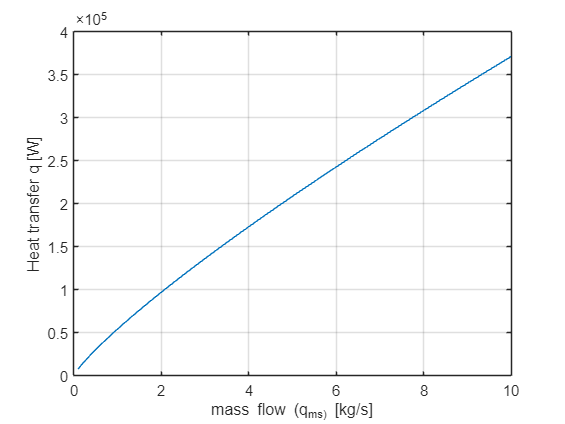


figure
plot(q_ms, qs)
xlabel('mass flow (q_ms) [kg/s]')
ylabel('Heat transfer q [W]')
grid('on')

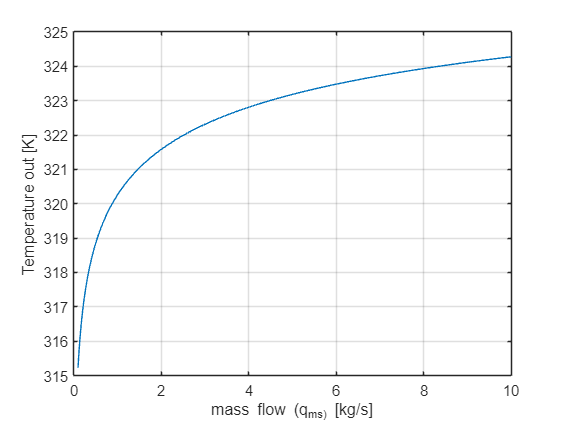


figure
plot(q_ms, T_o_sols)
xlabel('mass flow (q_ms) [kg/s]')
ylabel('Temperature out [K]')
grid('on')

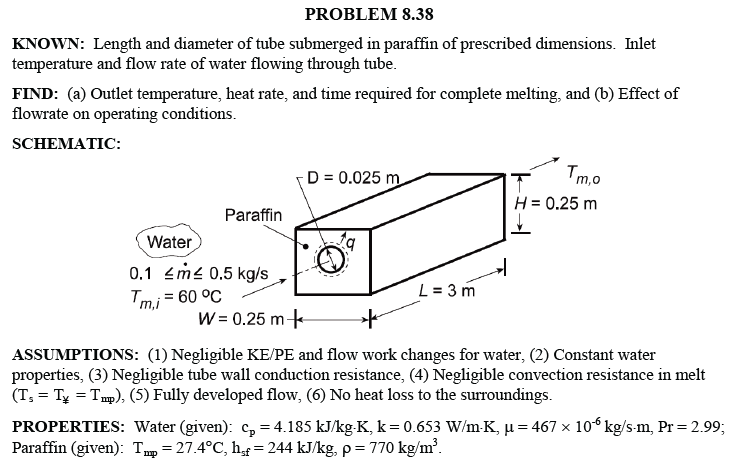

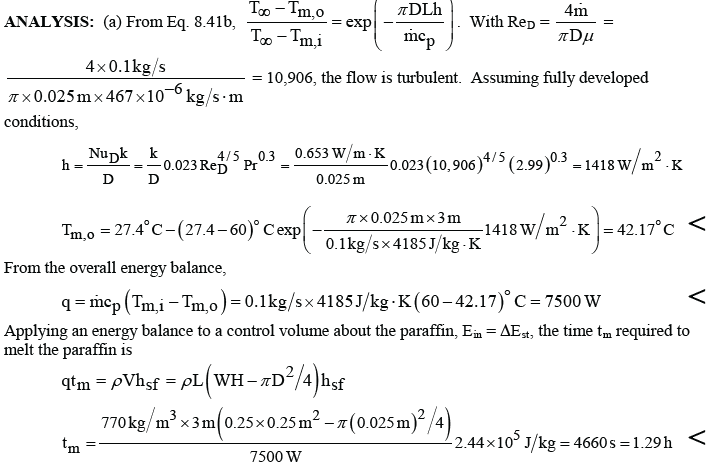

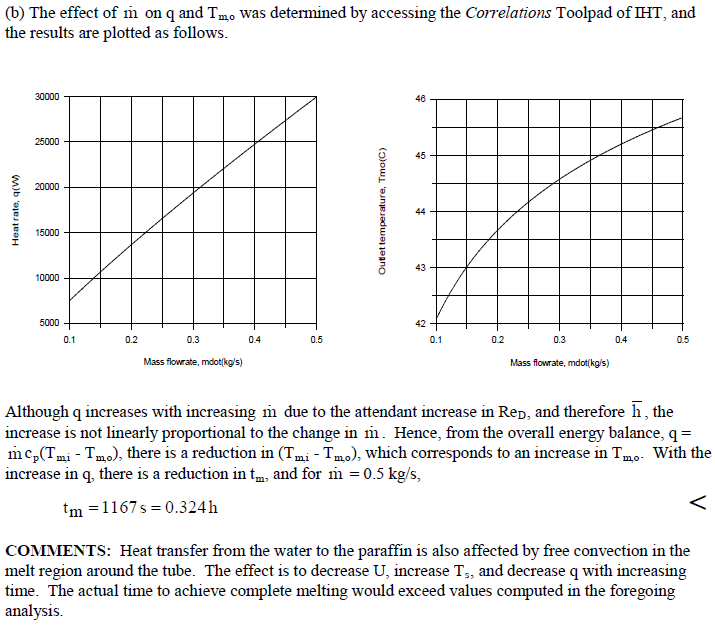

Opgave 8.67

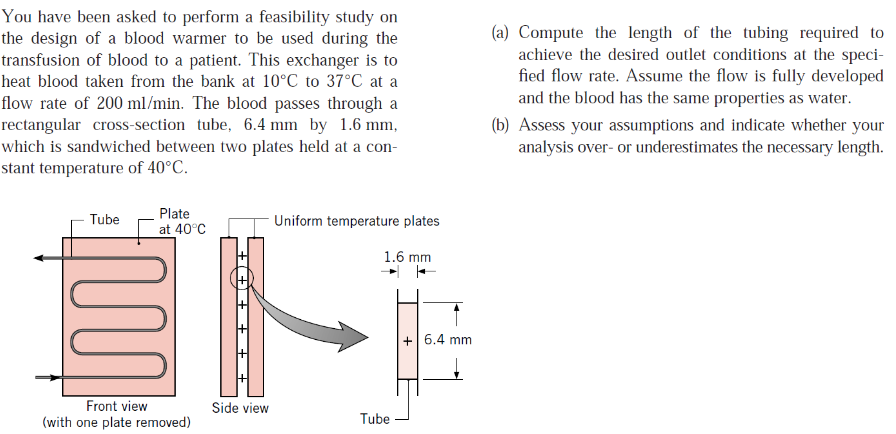

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P_atm = 101325; % Pascal eller 1e5
fluid = 'water'

fluid = 'water'

u = symunit;

q_V_lmin = 0.200 * u.l /u.min; % l/min
q_V = unitConvert(q_V_lmin, u.m^3 / u.s )

$$q\_V = \frac{1}{300000}\,\frac{m^{3}}{s}$$

q_V = double(separateUnits(q_V))

q_V =    3.3333e-06



T_i = 10 + 273.15; % K
T_f = 37 + 273.15; % K
T_m = (T_i + T_f)/2

T_m =        296.65


H = 6.4e-3; % m højde af gang
W = 1.6e-3; % m brede af gang
HW = H/W

HW =      4


Ac = H*W;
P = 2*H + 2*W; % parimeter (omkreds) af tuben
syms L % længden af tuben
As = P * L

$$As = \frac{2\,L}{125}$$

T_plate = 40 + 273.15; % pladernes temperatur

k = CoolProp.PropsSI('conductivity', 'P', P_atm, 'T', T_m, fluid)

k =       0.60403


c_p = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_m, fluid) %specificHeat_p

c_p =          4182


mu = CoolProp.PropsSI('viscosity', 'P', P_atm, 'T', T_m, fluid) %Dynamisk viscositet

mu =     0.0009213


rho = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_m, fluid) %Densitet

rho =        997.42



q_m = q_V * rho

q_m =     0.0033247


u = q_V / Ac

u =       0.32552


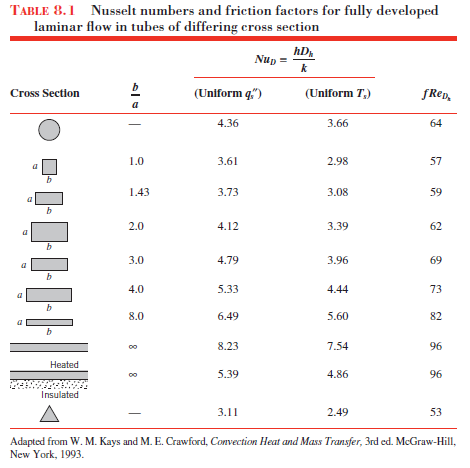

Dh = 4 * Ac / P

Dh =       0.00256


Re_D = rho * u * Dh / mu%4*q_m /( * mu)

Re_D =        902.18


Lamniar flow

Nu_D =  4.44 % from table 8.1 for ikke circular tværsnit

Nu_D =          4.44


% Nu_D = 3.66 % from table 8.4

h = Nu_D * k / Dh

h =        1047.6



T_s = T_plate;
T_0 = T_f

T_0 =        310.15



DT_lm = ( (T_s -T_i) - (T_s -T_0) ) / log( (T_s - T_i) / (T_s - T_0))

DT_lm =        11.726



q = (T_f - T_i) * q_m * c_p %varme tilførelsen fra indgang til udgang

q =        375.41


eq = q == As * h * DT_lm; % newtons kølings lov %varme tilførelsen fra omgivelser til blod
L_sol = double(solve(eq,L))

L_sol =          1.91



L_korrekt = 1.9 % m % det rigtige svar

L_korrekt =           1.9


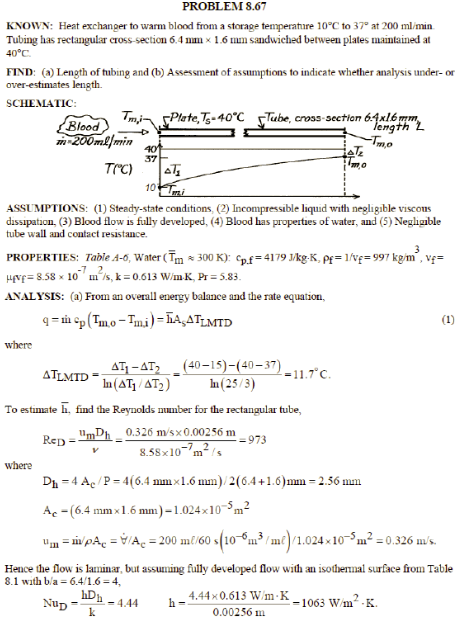

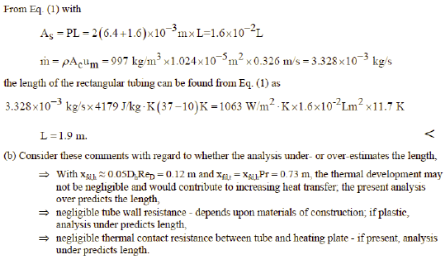

## Tabeller